clear
syms t A T real positive;

quarter_T = T / 4;

q_ddot = piecewise( ...
    t < quarter_T, A, ...
    t >= quarter_T & t < 3 * quarter_T, -A, ...
    t >= 3 * quarter_T, A ...
)

$$q\_ddot = \left\{ \begin{array}{cl} A & \text{ if }4\,t<T\\ -A & \text{ if }T\leq 4\,t\wedge 4\,t<3\,T\\ A & \text{ if }3\,T\leq 4\,t \end{array}\right.$$

q_dot = piecewise( ...
    t < quarter_T, A * t, ...
    t >= quarter_T & t < 3 * quarter_T, -A * (t - T/2), ...
    t >= 3 * quarter_T, A * (t - T) ...
)

$$q\_dot = \left\{ \begin{array}{cl} A\,t & \text{ if }4\,t<T\\ A\,\left(\frac{T}{2}-t\right) & \text{ if }T\leq 4\,t\wedge 4\,t<3\,T\\ -A\,\left(T-t\right) & \text{ if }3\,T\leq 4\,t \end{array}\right.$$

q = piecewise( ...
    t < quarter_T, 1/2 * A * t^2, ...
    t >= quarter_T & t < 3 * quarter_T, -1/16 * A * (8 * t^2 - 8 * T * t + T^2), ...
    t >= 3 * quarter_T, 1/2 * A * (t - T)^2 ...
)

$$q = \left\{ \begin{array}{cl} \frac{A\,t^{2}}{2} & \text{ if }4\,t<T\\ -\frac{A\,\left(T^{2}-8\,T\,t+8\,t^{2}\right)}{16} & \text{ if }T\leq 4\,t\wedge 4\,t<3\,T\\ \frac{A\,{\left(T-t\right)}^{2}}{2} & \text{ if }3\,T\leq 4\,t \end{array}\right.$$

$$ans = \frac{A\,T^{2}}{32}$$

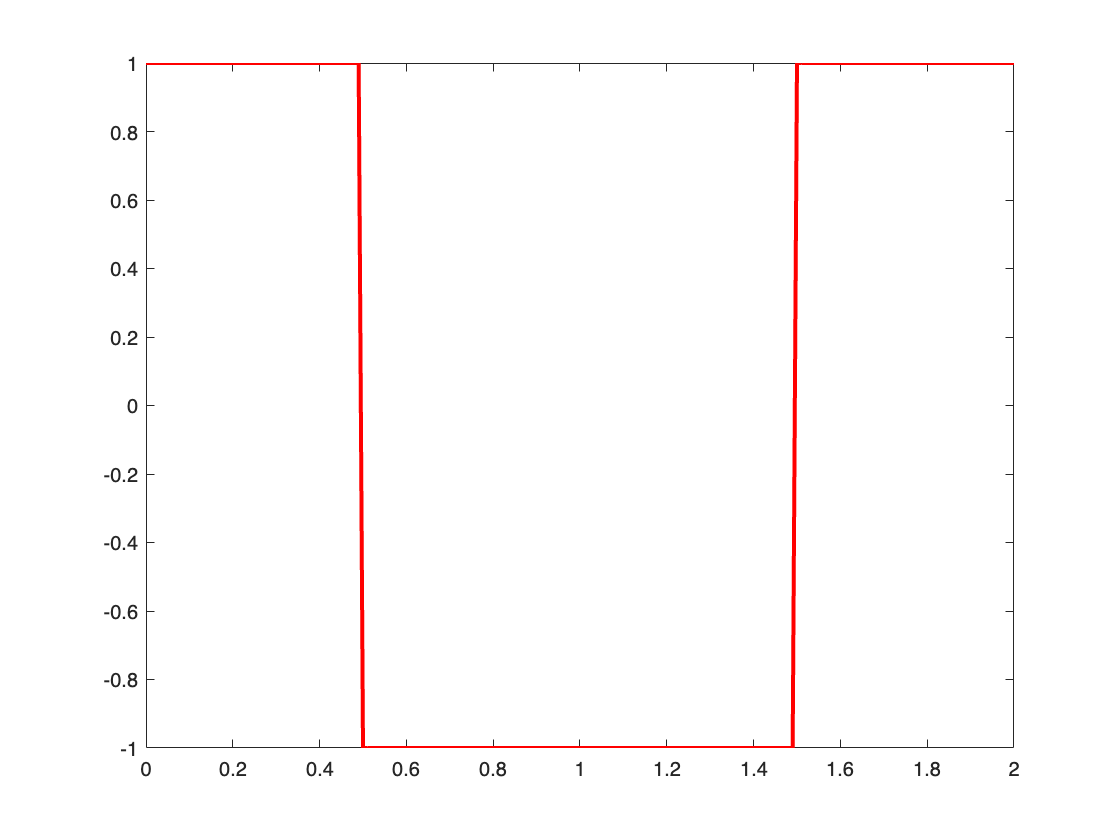

t_val = 0:0.01:2;
A_val = 1;
T_val = 2;

q_val = subs(q_ddot, t, t_val);
q_val = subs(q_val, [A, T], [A_val, T_val]);
plot(t_val, q_val, 'r', 'LineWidth', 2)

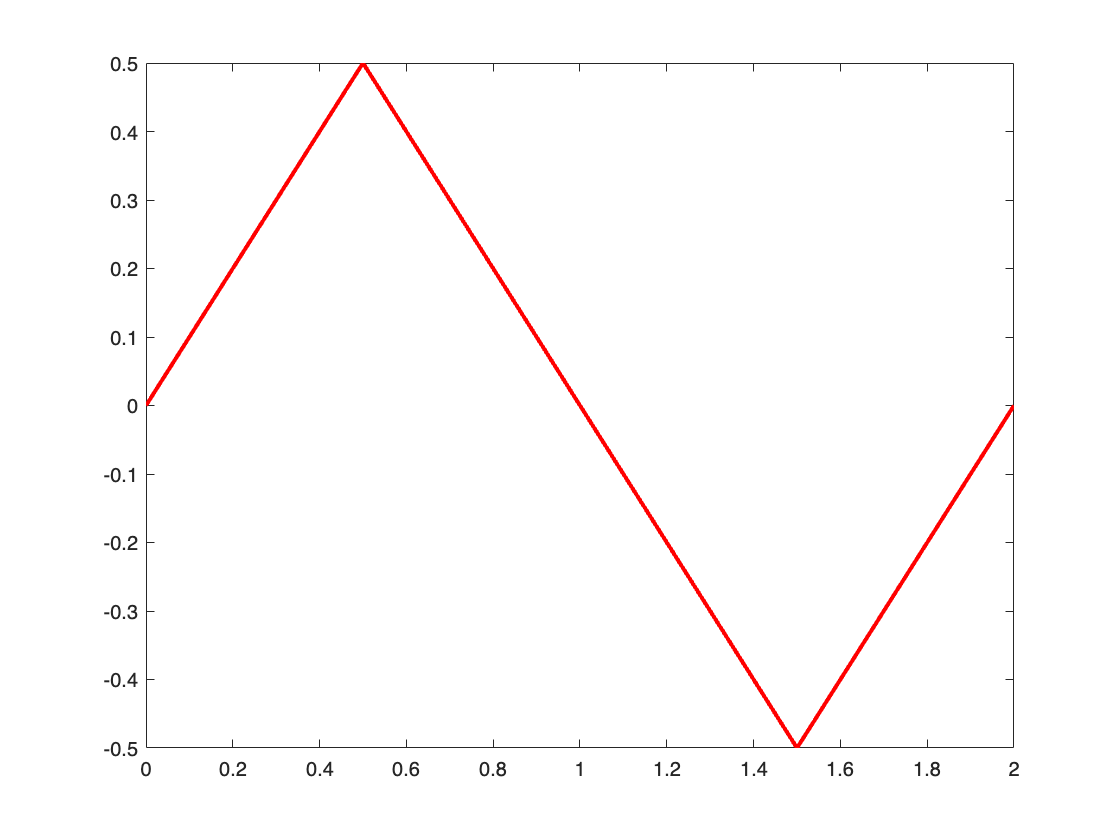

q_dot_val = subs(q_dot, t, t_val);
q_dot_val = subs(q_dot_val, [A, T], [A_val, T_val]);
plot(t_val, q_dot_val, 'r', 'LineWidth', 2)

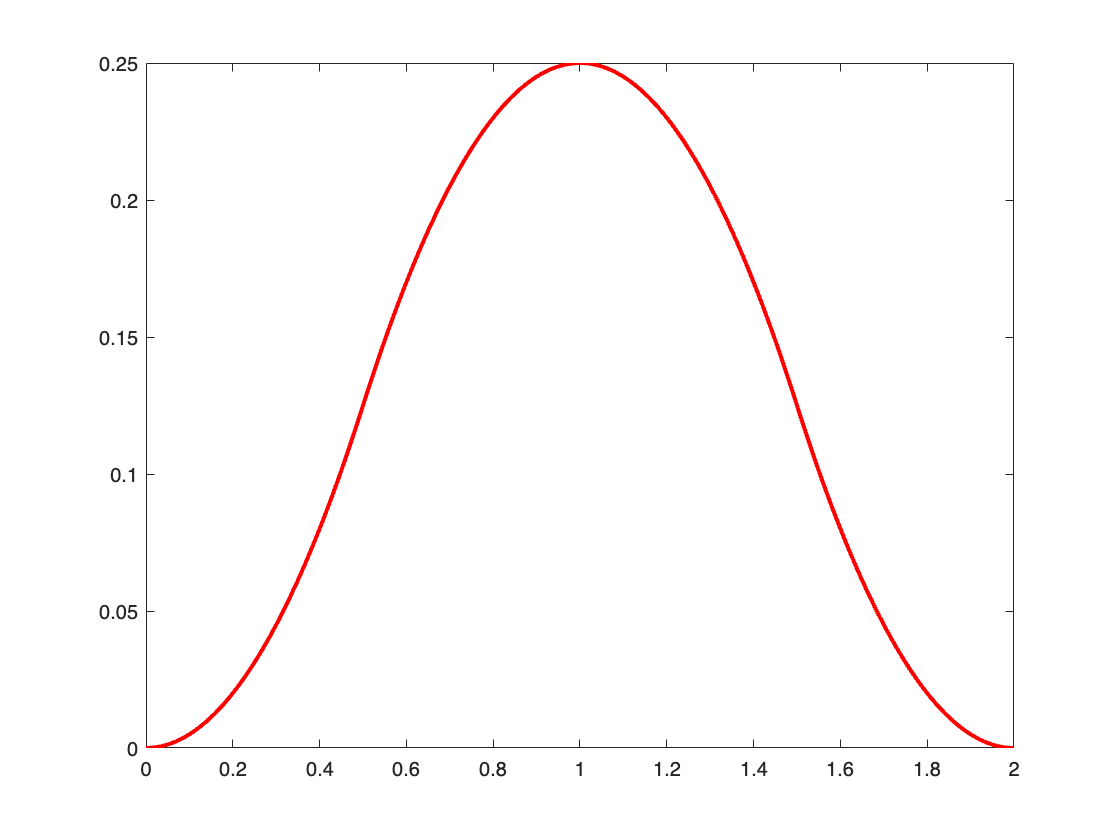

q_val = subs(q, t, t_val);
q_val = subs(q_val, [A, T], [A_val, T_val]);
plot(t_val, q_val, 'r', 'LineWidth', 2)